# Threshold Image of Bear Glacier

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

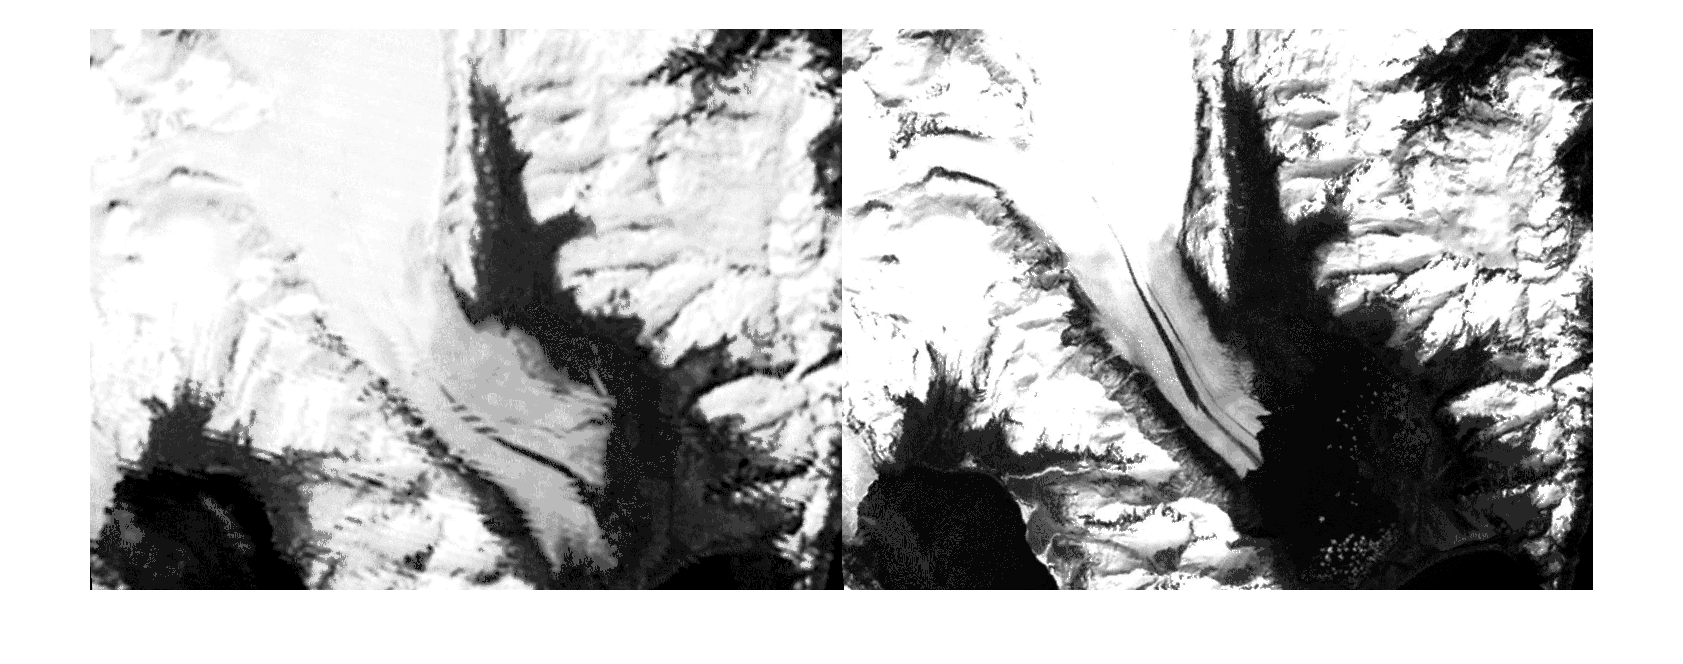

[glacier1980, map80] = imread("./images/bearGlacier1980.png");
gs1980 = ind2gray(glacier1980, map80);
gs1980 = im2double(gs1980);

[glacier2011, map11] = imread("./images/bearGlacier2011.png");
gs2011 = ind2gray(glacier2011, map11);
gs2011 = im2double(gs2011);

diffIce = gs1980 - gs2011;
diffIce = rescale(diffIce);
imshowpair(gs1980, gs2011, "montage")

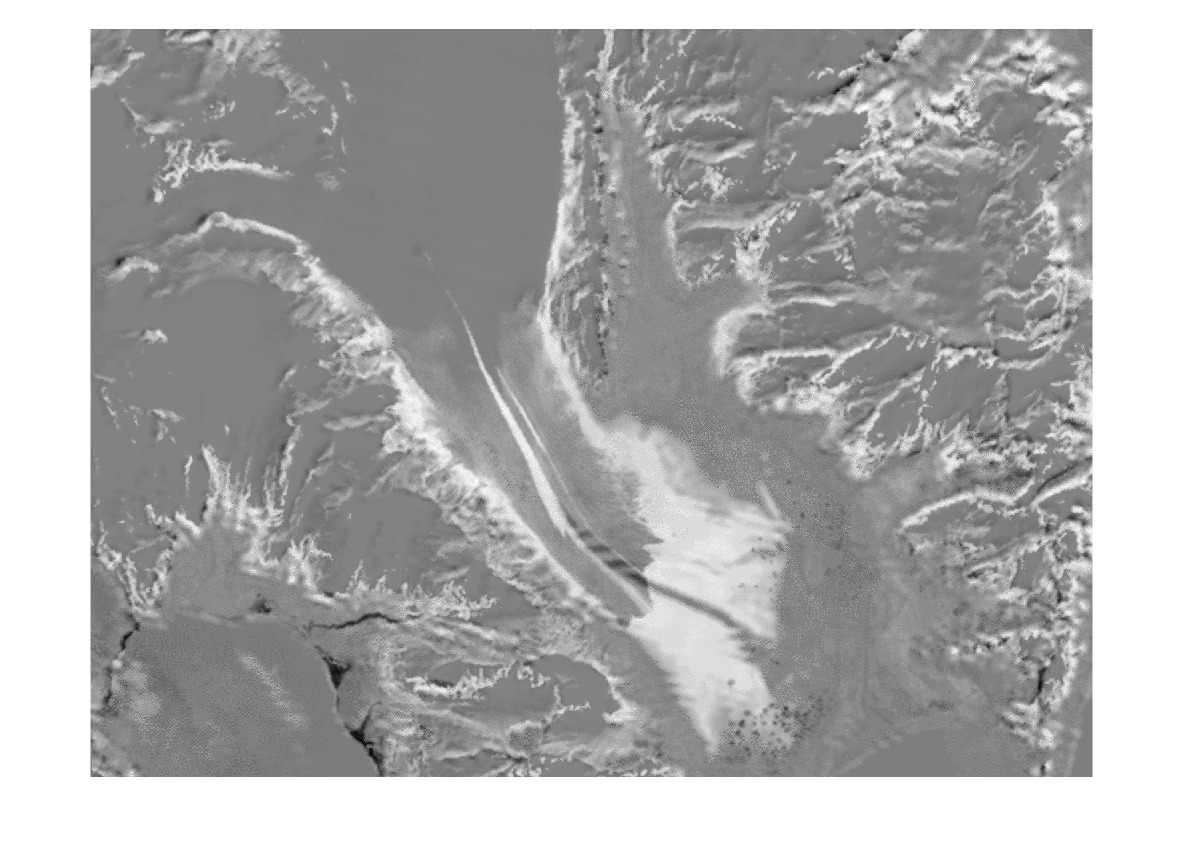

imshow(diffIce)

## Task 1

Bright regions of `diffIce` (e.g. areas that are close to white) represent places where there was more ice in 1980 than in 2011. This can be interpreted as lost ice over that time period.

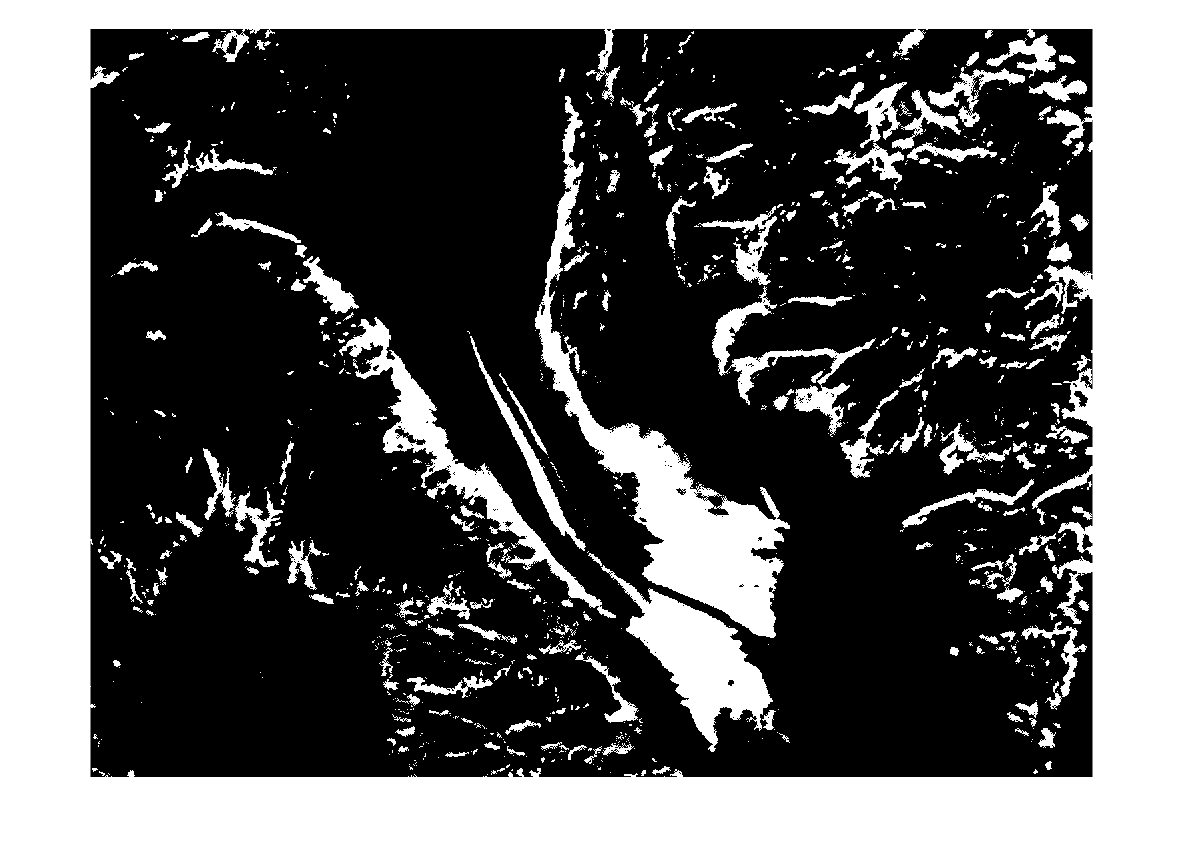

ice1980 = diffIce > .7;
imshow(ice1980)

## Task 2

Dark regions of `diffIce` represent the ice gained between 1980 and 2011.

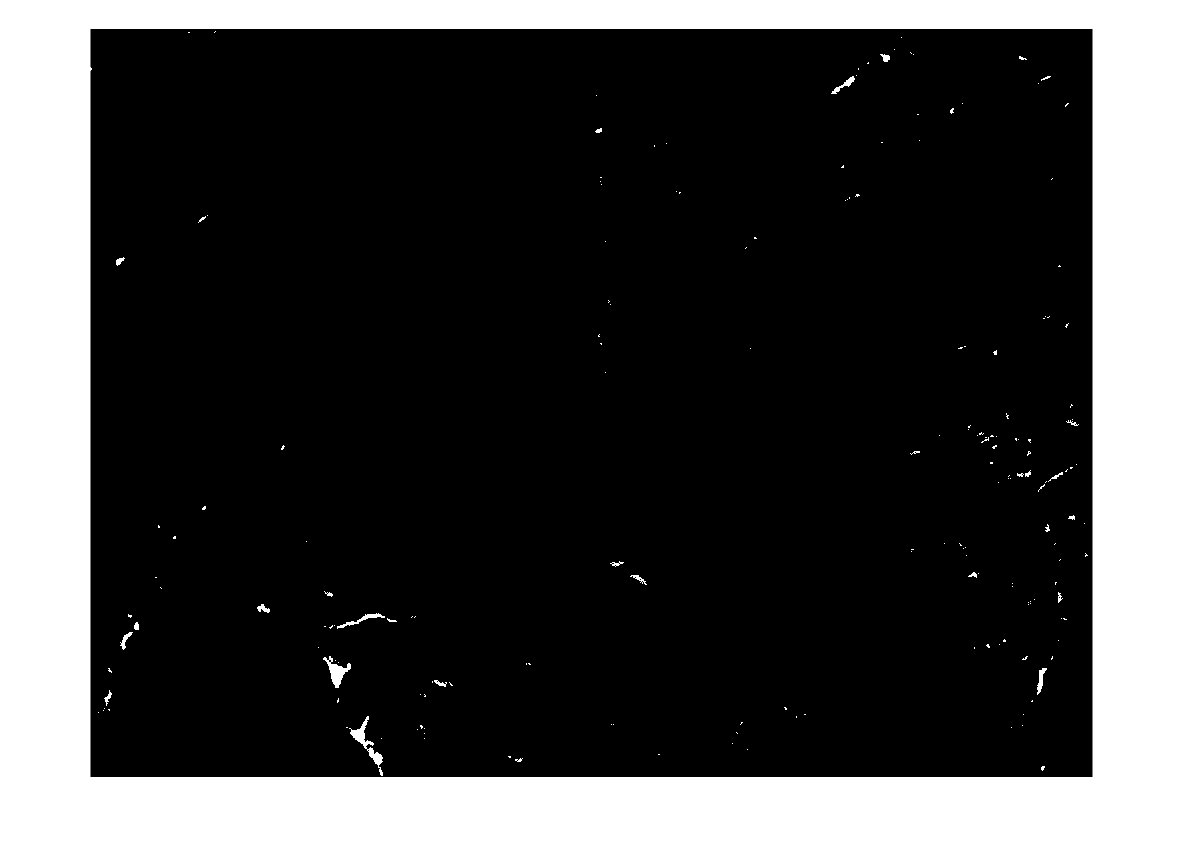

ice2011 = diffIce < .3;
imshow(ice2011)

## Task 3

You can see in `ice2011` that there was not a significant amount of ice gained from 1980 to 2011.

To calculate the percent of the image that lost ice, you need to compare the number of white pixels in `ice1980` to the total number of pixels in the image.

To count the number of nonzero (or white) elements in a segmentation, you can use the `nnz` function.

`nnz``(``BW``)`

To calculate the total number of pixels in an image, use the `numel` function.

`numel``(``BW``)`

Then calculate the percent change.


$$\frac{\mathrm{Nonzero}\mathrm{pixels}}{\mathrm{Total}\mathrm{pixels}}\mathrm{x100}$$


iceAmt1980 = nnz(ice1980)

iceAmt1980 = 223079

numPixels = numel(ice1980)

numPixels = 1683742

melt = iceAmt1980 / numPixels * 100

melt = 13.2490